Se inicia con la descarga de datos.

datos = readtable('datos_personas.xlsx', 'VariableNamingRule', 'preserve')

Error using readtable (line 517)
Unable to find or open 'datos_personas.xlsx'. Check the path and filename or file permissions.

Se crea un gráfico de tres variables.

alturas = datos.("Altura(m)");
pesos = datos.("Peso(kg)");
imcs = datos.IMC;

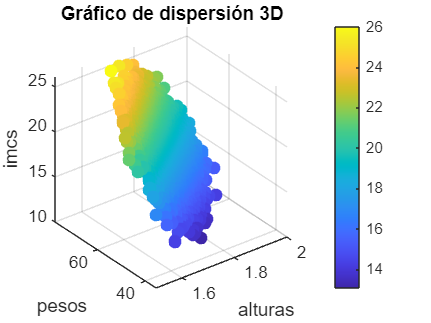

figure;
scatter3(alturas, pesos, imcs, 50, imcs, 'filled'); 
grid on;
xlabel('alturas');
ylabel('pesos');
zlabel('imcs');
title('Gráfico de dispersión 3D');
colorbar; 

% Reducción a una variable entre altura y peso
base_altura_peso = [alturas, pesos];

Unrecognized function or variable 'alturas'.

[coeff, score, latent] = pca(base_altura_peso); % score contiene las componentes principales
primera_componente = score(:, 1); % primera
segunda_componente = score(:,2); %segunda
varianza_total = sum(latent)

proporcion_varianza = latent / sum(latent)  % Proporciones de varianza para componente 1 y 2
varianza_exp

% La segunda componente es irrelevante

% Calcular correlaciones originales y transformadas
% Correlaciones originales
correlacion_peso_altura = corr(alturas,pesos);
correlacion_peso_imc = corr(pesos, imcs);
correlacion_altura_imc = corr(alturas, imcs);
correlacion_promedio = (correlacion_peso_altura+correlacion_peso_imc+correlacion_altura_imc)/3

correlacion_promedio = 0.3923


% Correlaciones transformadas
correlacion_transformada = corr(primera_componente, imcs)

correlacion_transformada = 0.7955

% Correlacion al aplicar apc al componente generado con peso y altura con IMCs
base_componente_imcs = [primera_componente, imcs];
[coeff2, score2, latent2] = pca(base_componente_imcs)

coeff2 =     0.9723   -0.2339
    0.2339    0.9723


score2 =    -6.4381    0.5575
    4.0186   -1.5417
   12.1489    0.1807
    7.2386    0.5038
    8.2377    0.8529
   -1.8884   -0.5254
    6.6138   -0.4639
    4.1967   -0.7522
   -6.9974   -0.5654
   -2.8979    0.3895


latent2 =    29.5482
    0.8375



% Varianza y proporción
varianza_total2 = sum(latent2)

varianza_total2 = 30.3856

proporcion_varianza2 = latent2 / varianza_total2 

proporcion_varianza2 =     0.9724
    0.0276


% Se compara PCA entre las tres variables y solo altura/peso
datos_tres_variables = [alturas, pesos, imcs];
[coeff_3, score_3, latent_3] = pca(datos_tres_variables);

% Variabilidades
varianza_total2 = sum(latent_3)

varianza_total2 = 30.3874

proporcion_varianza_nuevo = latent_3 / sum(latent_3)

proporcion_varianza_nuevo =     0.9724
    0.0276
    0.0000



% La tercera componente no explica nada directamente, y la segunda un 2.76%

% Filtrar valores extremos y repetir ACP
% Criterio de filtrado: cualtiles 5% y 95%

% Ordenar la base en función de la altura
base_ordenada_por_altura = sortrows(datos, 'Altura(m)');

% Definir el filtro basado en altura para la base ordenada
lim_inf_altura = quantile(base_ordenada_por_altura.("Altura(m)"), 0.05);
lim_sup_altura = quantile(base_ordenada_por_altura.("Altura(m)"), 0.95);

% Crear el filtro
filtro_altura = (base_ordenada_por_altura.("Altura(m)")  >= lim_inf_altura) & (base_ordenada_por_altura.("Altura(m)") <= lim_sup_altura);

% Aplicar el filtro a la base ordenada
base_filtrada_altura = base_ordenada_por_altura(filtro_altura, :);

% Tamaños antes y depeues
disp('Tamaño de la base original:');

Tamaño de la base original:


disp(height(datos));

       25000



disp('Tamaño de la base filtrada:');

Tamaño de la base filtrada:


disp(height(base_filtrada_altura));

       22500



Correlaciones originales con IMC después del filtrado:


   -0.1206
    0.7970



Correlación de la primera componente principal con IMC después del filtrado:


    0.7970



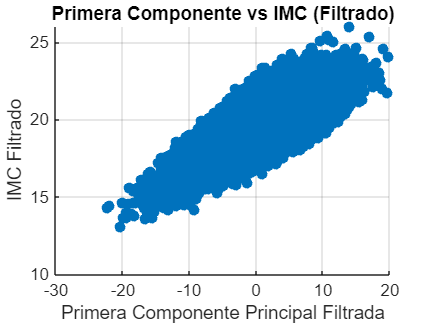

% ACP usando la base filtrada
datos_filtrados_altura = [base_filtrada_altura.("Altura(m)"), base_filtrada_peso.("Peso(kg)")];
[coeff_filtr_alt, score_filtr_alt, latent_filtr_alt] = pca(datos_filtrados_altura);

% Varianzas con el filtro
varianzas_filtro_alt = latent_filtr_alt/sum(latent_filtr_alt)

% Correlaciones con IMC después del filtrado
correlaciones_filtradas_alt = corr([base_filtrada_altura.("Altura(m)"), base_filtrada_altura.("Peso(kg)")], base_filtrada_altura.IMC)

% Gráficos
figure;
scatter(score_filtr_alt(:, 1), base_filtrada_altura.IMC, 'filled');
xlabel('Primera Componente Principal Filtrada');
ylabel('IMC Filtrado');
title('Primera Componente vs IMC (Filtrado)');
grid on;

% Criterio de filtrado: rango intercuartílico en pesos
% Ordenar la base en función del peso
base_ordenada_por_peso = sortrows(datos, 'Peso(kg)');

% Definir el filtro basado en peso para la base ordenada
lim_inf_peso = quantile(base_ordenada_por_peso.("Peso(kg)"), 0.05);
lim_sup_peso = quantile(base_ordenada_por_peso.("Peso(kg)"), 0.95);

% Crear el filtro 
filtro_peso = (base_ordenada_por_peso.("Peso(kg)")  >= lim_inf_peso) & (base_ordenada_por_peso.("Peso(kg)") <= lim_sup_peso);

% Aplicar el filtro a la base ordenada
base_filtrada_peso = base_ordenada_por_peso(filtro_peso, :);

%tamaños de la base antes y después del filtrado
disp('Tamaño de la base original:');

Tamaño de la base original:


disp(height(datos));

       25000



disp('Tamaño de la base filtrada:');

Tamaño de la base filtrada:


disp(height(base_filtrada_peso));

       22500



% Continuar con el ACP usando la base filtrada
datos_filtrados_peso = [base_filtrada_peso.("Altura(m)"), base_filtrada_peso.("Peso(kg)")];
[coeff_filtr_peso, score_filtr_peso, latent_filtr_peso] = pca(datos_filtrados_peso);

% Varianzas con el filtro
varianzas_filtro_peso = latent_filtr_peso/sum(latent_filtr_peso)

varianzas_filtro_peso =     0.9999
    0.0001



% Calcular correlaciones con IMC después del filtrado
correlaciones_filtradas_peso = corr([base_filtrada_peso.("Altura(m)"), base_filtrada_peso.("Peso(kg)")], base_filtrada_peso.IMC)

correlaciones_filtradas_peso =    -0.3336
    0.7154


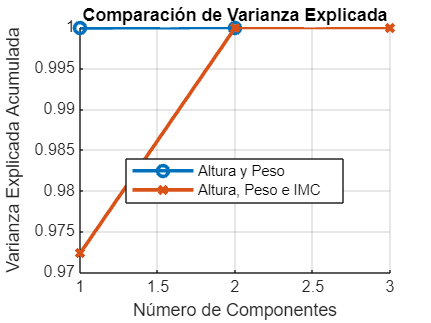


% Gráficos
figure;
scatter(score_filtr_peso(:, 1), base_filtrada_peso.IMC, 'filled');
xlabel('Primera Componente Principal Filtrada');
ylabel('IMC Filtrado');
title('Primera Componente vs IMC (Filtrado)');
grid on;

% Criterio de filtrado: cuantiles 5% y 95%

% Ordenar la base en función del IMC
base_ordenada_por_imc = sortrows(datos, 'IMC');

% Definir el filtro basado en altura para la base ordenada
lim_inf_imc = quantile(base_ordenada_por_imc.("IMC"), 0.05);
lim_sup_imc = quantile(base_ordenada_por_imc.("IMC"), 0.95);

% Crear el filtro
filtro_imc = (base_ordenada_por_imc.("IMC")  >= lim_inf_imc) & (base_ordenada_por_imc.("IMC") <= lim_sup_imc);

% Aplicar el filtro a la base ordenada
base_filtrada_imc = base_ordenada_por_imc(filtro_imc, :);

% Tamaños antes y después
disp('Tamaño de la base original:');

Tamaño de la base original:


disp(height(datos));

       25000



disp('Tamaño de la base filtrada:');

Tamaño de la base filtrada:


disp(height(base_filtrada_imc));

       22500



Correlaciones originales con IMC después del filtrado:


   -0.1209
    0.7938



Correlación de la primera componente principal con IMC después del filtrado:


    0.7937



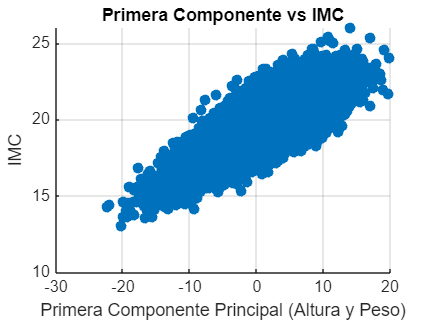

% ACP usando la base filtrada
datos_filtrados_imc = [base_filtrada_imc.("Altura(m)"), base_filtrada_peso.("Peso(kg)")];
[coeff_filtr_imc, score_filtr_imc, latent_filtr_imc] = pca(datos_filtrados_imc);

% Varianzas con la base filtrada
varianzas_filtro_imc = latent_filtr_imc/sum(latent_filtr_imc)

% Correlaciones con IMC después del filtrado
correlaciones_filtradas_imc = corr([base_filtrada_imc.("Altura(m)"), base_filtrada_imc.("Peso(kg)")], base_filtrada_imc.IMC)

% Gráficos
figure;
scatter(score_filtr_imc(:, 1), base_filtrada_imc.IMC, 'filled');
xlabel('Primera Componente Principal Filtrada');
ylabel('IMC Filtrado');
title('Primera Componente vs IMC (Filtrado)');
grid on;